% MATLAB LABORATORIO CALCULO. 
% CALCULO SIMBOLICO / TOOLBOX SYMBOLIC

% Estudio de una función
syms x
y = x/(1+x^2)

$$y = \frac{x}{x^{2}+1}$$

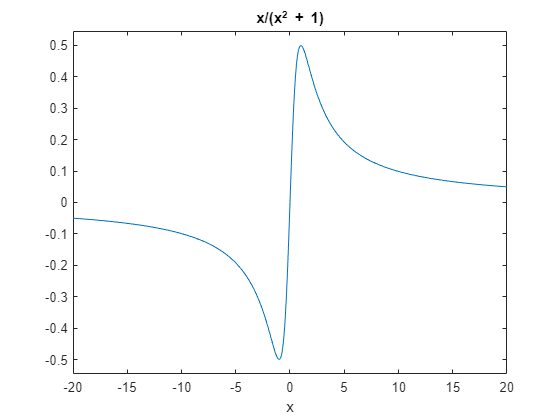

% Grafica
ezplot(y,[-20,20])

% Estudio de Máximos y mínimos
% Calcular los puntos donde la primera derivada de la función es cero
y1 = simplify(diff(y))

$$y1 = -\frac{x^{2}-1}{{\left(x^{2}+1\right)}^{2}}$$

max_min = solve(y1)

$$max\_min = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

% Comprobar si son maxímos o mínimos sustituyendo los valores en la segunda derivada
y2 = simplify(diff(y,2)) 

$$y2 = \frac{2\,x\,\left(x^{2}-3\right)}{{\left(x^{2}+1\right)}^{3}}$$

subs(y2,max_min)

$$ans = \left(\begin{array}{c} \frac{1}{2}\\ -\frac{1}{2} \end{array}\right)$$

% Estudio de concavidad y convexidad
puntos_criticos_x = solve(y2)

$$puntos\_criticos\_x = \left(\begin{array}{c} 0\\ \sqrt{3}\\ -\sqrt{3} \end{array}\right)$$

punto_criticos_y = subs(y,puntos_criticos_y)

$$punto\_criticos\_y = \left(\begin{array}{c} 0\\ \frac{\sqrt{3}}{4}\\ -\frac{\sqrt{3}}{4} \end{array}\right)$$

% Comprobamos en cada uno de los rangos 
% -inf < x < -sqrt(3)
% y2 < 0 es convexa desde -inf < x < -sqrt(3)
subs(y2,-5)

$$ans = -\frac{55}{4394}$$

% -sqrt(3) < x < 0
% y2 > 0 es concava desde -sqrt(3) < x < 0
subs(y2,-0.5)

$$ans = \frac{176}{125}$$

% 0 < x < sqrt(3)
% y2 < 0 es convexa desde 0 < x < sqrt(3)
subs(y2,0.5)

$$ans = -\frac{176}{125}$$

% sqrt(3) < x < inf
% y2 > 0 es concava desde sqrt(3) < x < inf
subs(y2,5)

$$ans = \frac{55}{4394}$$